obj = ProgressClass;
Behav = obj.BehavTable;
Color = GPSColor;

plotsize1 = [7 3];

%% get bahavior index
ind_portL       = Behav.PortCorrect==1;
ind_portR       = Behav.PortCorrect==2;

ind_short       = Behav.Stage==1 & Behav.FP==0.5;
ind_med         = Behav.Stage==1 & Behav.FP==1;
ind_long        = Behav.Stage==1 & Behav.FP==1.5;

ind_correct     = strcmp(Behav.Outcome, 'Correct');
ind_correctL    = ind_portL & ind_correct;
ind_correctR    = ind_portR & ind_correct;

ind_wrong       = strcmp(Behav.Outcome, 'Wrong');
ind_wrongL      = ind_portL & ind_wrong;
ind_wrongR      = ind_portR & ind_wrong;

ind_late        = (strcmp(Behav.Outcome, 'LateCorrect') | strcmp(Behav.Outcome, 'LateWrong'));
ind_lateL       = ind_portL & ind_late;
ind_lateR       = ind_portR & ind_late;

ind_premature   = strcmp(Behav.Outcome, 'Premature');
ind_prematureL  = ind_portL & ind_premature;
ind_prematureR  = ind_portR & ind_premature;

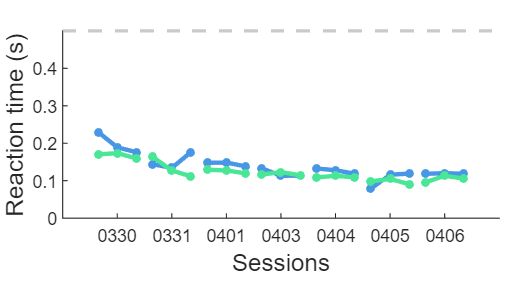

actualfont = 'Arial'

fig = figure(22); clf(22);
set(gcf, 'unit', 'centimeters', 'position',[2 2 plotsize1+1.5], 'paperpositionmode', 'auto', 'color', 'w')

ha4 = axes;
set(ha4, 'units', 'centimeters', 'position', [1 1, plotsize1], 'nextplot', 'add', 'ylim', [0 0.5], 'xlim', [0 obj.NumSessions+1], ...
    'xtick', 1:obj.NumSessions, 'xticklabel', cellfun(@(x) x(5:end), obj.Sessions, 'UniformOutput', false),...
    'yscale', 'linear', 'fontsize', 8, 'FontName', 'Arial')

xlabel('Sessions', 'fontsize', 11)
ylabel('Reaction time (s)', 'fontsize', 11)

yline(0.5, 'Color', [.7 .7 .7], 'LineWidth', 1.5, 'LineStyle', '--');

for s = 1:obj.NumSessions
    for p = 1:2
        plot([s-0.35 s s+0.35], obj.RTStat.MedianRT(obj.RTStat.Port==obj.Ports(p) & obj.RTStat.Sessions==obj.Sessions{s} & obj.RTStat.thisFP~=0), ...
            'Color', eval("Color.Port"+obj.Ports(p)), 'LineWidth', 2, 'Marker', 'o', 'MarkerSize', 2);
    end
end

print(fig, '-dpng', 'RTTrack')
printeps(22, 'RTTrack');